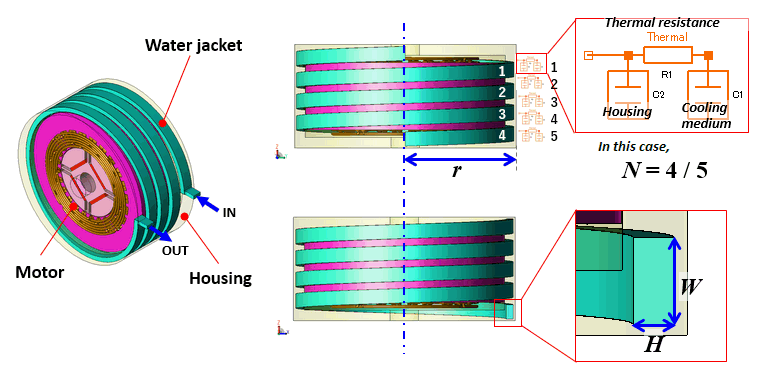

function R = calcRthWaterJacket(C_F, h, r, W, N)
    % Calculate the thermal resistance of a water jacket.
    %
    % Parameters:
    % C_F: Correction factor (Default: 1)
    % h: Heat transfer coefficient (W/m²/°C)
    % r: Radius of the cooling target (mm)
    % W: Width of the cooling target (mm)
    % N: Number of thermal resistor components
    %
    % Returns:
    % R: Thermal resistance value (°C/W)


$$R=C_F \times \frac{1}{h \times A}$$



$$$R$ : Thermal resistance value ( $\mathrm{deg} \mathrm{C} / \mathrm{W})$
$C_F$ : Correction factor: (Default: 1 )
$h$ : Heat transfer coefficient (described below)
A: Area of the cooling target per single Thermal Resistor component ( $\mathrm{mm}^{\wedge} 2$ ) (described below)$$



$$A=2 \pi r W N$$


다음 입력 값을 검색 조건으로 하여 JMAG의 열전달계수 실제 측정값 표에서 열전달계수를 검색합니다:

Coolant Type

Flow Velocity v

W,H

열전달 계수의 실제 측정값 표는 공개되지 않습니다.

    % Calculate the area
    A = 2 * pi * r * W * N;  % Area in mm²

    % Convert A from mm² to m²
    A_m2 = A / (1000 * 1000);  % Convert mm² to m²

    % Calculate thermal resistance
    R = C_F * (1 / (h * A_m2));
end
